# Unveiling iPD Modulation

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

% Settings
dirIn          = "../waves/recordings/PhaseModulationAnalysis/";
dirPlotData    = dirIn+"plotdata/";
forceRecompute = false; % Force recomputation of phase modulation (takes veeery long)
                        % If false, load pre-computed results from data files 

## 1   Problem Statement

From the VZ-1 manual I got the (wrong) impression that "phase modulation" of the two oscillator signals of one line would work something like this:

    
$$y(t) = x_2\big(2\pi f_{02}t + h\pi x_1(2\pi f_{01}t)\big),$$


i.e., what I would consider a "normal" phase modulation. In the formula, $f_{01}$ and $f_{02}$ denote the note frequencies of two oscillators---say `M1` and `M2`---, $x_1(t)$ and $x_2(t)$ their output signals, $h$ the modulation index, i.e., the modulation "depth", and $y(t)$ the phase modulated signal. I further assume that $x_1$ and $x_2$ are periodic with a cycle length of $2\pi$ and take values $-1\leq x\leq 1$.

Some little measurements phase modulating two sine signals of the same frequency 

     $x_{SINE}(t) = \sin(2\pi f_0t-\pi)$      --- the SINE oscillator signal of the VZ comes with a phase offset of $-\pi$ ---

showed that it *does not* work this way:

- The note frequency $f_{01}$ of $x_1(t)$ does not seem to matter at all. Detuning $x_1$ does not have any influence on the phase-modulated signal $y(t)$.

- This phase modulated-line signal $y(t)$ itself looks other than expected.

- The amplitude of the modulated signal seems to vary with the modulation index $h$ (which should not happen with any kind of phase modulation).

So what *does* VZ's iPDM do?

## 2   Reverse-Engineering iPDM

### 2.1   Test Recordings of VZ-1

To puzzle out what is going on, I did some some test recordings of VZ-1. I proceeded as follows:

- Set the master tune in `Menu 3-00` to `TUNE(A4)=440.0`(Hz),

- Initialize a new voice `Menu 1-00`...`Menu 1-18`: [Copy/Initialize]+[YES], for all modules `M1`...`M8` where applicable,

- Deactivate all modules except `M1` and `M2`,

- Set `M1` and `M2` to fix pitch: `Menu 1-02`, `PITCH FIX=ON (x1)`,` OCT=02`,` NOTE=00`,` FINE=09`,

- Set `INT LINE=PHASE` for modules `M1` and `M2` in `Menu 0-00` (except recording #1),

- Set `FORM=<xxx>` for modules `M1` and `M2` in `Menu 0-01` according to table below,

- Set modulation index in `Menu 1-09`, `ENV DEPTH=<nn>` according to table below,

- Record the phase modulated output signal at a sampling frequency of 48 kHz (a cycle will be 1024 samples long with the fix pitch settings above),

- Manually label the zero-crossings of a falling edge in all recordings (approx. 10 cycles into the wave), and

- Automatically cut out one waveform cycle, i.e., 1024 samples, starting at the labeled position.

Overview of recordings and settings:

%  ---------------------------------------------------------------------------------------------
%  No.   M1    M2    M1 ENV DEPTH  File in "<vVZ>/waves/recordings/phase modulation measurement"
%  ---------------------------------------------------------------------------------------------
%   1    SINE  OFF   n/a           "M1=SINE, 46.875 Hz.wav"
%   2    SINE  SINE  00            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00"
%   3    SINE  SINE  09            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09"
%   4    SINE  SINE  19            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19"
%   5    SINE  SINE  29            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%   6    SINE  SINE  39            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39"
%   7    SINE  SINE  49            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49"
%   8    SINE  SINE  59            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59"
%   9    SINE  SINE  69            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69"
%  10    SINE  SINE  79            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79"
%  11    SINE  SINE  89            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89"
%  12    SINE  SINE  99            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99"
%  13    SAW1  SINE  29            "M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  14    SAW2  SINE  29            "M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  15    SAW3  SINE  29            "M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  16    SAW4  SINE  29            "M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  17    SAW5  SINE  29            "M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  ---------------------------------------------------------------------------------------------

Let's first load and cut the recordings:

fprintf(['_____________________________________________________________________\n' ...
 'Loading and cutting recordings']);

_____________________________________________________________________
Loading and cutting recordings


pfx  = 'recordings/phaseModulationAnalysis/';
rlst = [ vVZtools.listRecordings([pfx '.*M1=SINE']);
         vVZtools.listRecordings([pfx '.*M1=SAW' ]) ];

N    = length(rlst); % The number of recordings
name = strrep(rlst,pfx,'');
wave = cell(N,1);    % The cut waveforms
a    = ones(N,1);    % The waveform amplitudes
h    = ones(N,1);    % Approximate modulations depths

for i=1:N
  fprintf('%s',name{i});
  [wav,pm,props] = vVZtools.loadRecording(rlst{i});
  wave{i} = vVZtools.cutNiceCycle(wav,pm,[7 length(pm)-3],1024);
  K       = length(wave{i});
  x_mean  = mean(wave{i});
  wave{i} = wave{i} - x_mean;   % Remove DC
  x_max   = max(wave{i});
  x_min   = min(wave{i});
  a(i)    = max(x_max,-x_min);
  h(i)    = vVZtools.parseKeyVal(props.value,'1-10.M1.ENV_DEPTH','%d');
  h(i)    = h(i)/100;
  if i==1; h(1)=0; end % Just for plot optimization
  fprintf('Cycle:\n')
  fprintf('  %g <= x <= %g\n',x_min,x_max);
  fprintf('  K    = %d\n',K     );
  fprintf('  mean = %g\n',x_mean);
  fprintf('  a    = %g\n',a(i)   );
  fprintf('  h    = %f\n',h(i)   );
end

M1=SINE, 46.875 Hz

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, 46.875 Hz")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, 46.875 Hz.wav"
  - OK, 79260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, 46.875 Hz.par"
  - Read properties
    - OK, 9 properties
  - Read pitch marks
    - OK, 44 pitch marks


Cycle:


  -0.314964 <= x <= 0.314614


  K    = 1024


  mean = -0.000313312


  a    = 0.314964


  h    = 0.000000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00.wav"
  - OK, 131760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 71 pitch marks


Cycle:


  -0.217973 <= x <= 0.217818


  K    = 1024


  mean = -7.4774e-05


  a    = 0.217973


  h    = 0.000000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09.wav"
  - OK, 73260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 41 pitch marks


Cycle:


  -0.329046 <= x <= 0.328883


  K    = 1024


  mean = -0.000361145


  a    = 0.329046


  h    = 0.090000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19.wav"
  - OK, 62760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 37 pitch marks


Cycle:


  -0.388997 <= x <= 0.388682


  K    = 1024


  mean = -0.000285029


  a    = 0.388997


  h    = 0.190000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 52260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 41 pitch marks


Cycle:


  -0.415602 <= x <= 0.415147


  K    = 1024


  mean = -0.000352502


  a    = 0.415602


  h    = 0.290000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39.wav"
  - OK, 55260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 38 pitch marks


Cycle:


  -0.392388 <= x <= 0.391761


  K    = 1024


  mean = -0.000281364


  a    = 0.392388


  h    = 0.390000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49.wav"
  - OK, 53760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 38 pitch marks


Cycle:


  -0.358911 <= x <= 0.358588


  K    = 1024


  mean = -0.000311166


  a    = 0.358911


  h    = 0.490000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59.wav"
  - OK, 49260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 37 pitch marks


Cycle:


  -0.425563 <= x <= 0.425206


  K    = 1024


  mean = -0.000309676


  a    = 0.425563


  h    = 0.590000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69.wav"
  - OK, 61260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 38 pitch marks


Cycle:


  -0.341293 <= x <= 0.340866


  K    = 1024


  mean = -0.000320524


  a    = 0.341293


  h    = 0.690000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79.wav"
  - OK, 68760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 36 pitch marks


Cycle:


  -0.412983 <= x <= 0.412335


  K    = 1024


  mean = -0.000347286


  a    = 0.412983


  h    = 0.790000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89.wav"
  - OK, 61260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 39 pitch marks


Cycle:


  -0.39336 <= x <= 0.392894


  K    = 1024


  mean = -0.000438362


  a    = 0.39336


  h    = 0.890000


M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99.wav"
  - OK, 58260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 39 pitch marks


Cycle:


  -0.391766 <= x <= 0.391529


  K    = 1024


  mean = -0.000293612


  a    = 0.391766


  h    = 0.990000


M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 86760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 44 pitch marks


Cycle:


  -0.4487 <= x <= 0.384674


  K    = 1024


  mean = -0.000365913


  a    = 0.4487


  h    = 0.290000


M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 82260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 47 pitch marks


Cycle:


  -0.480205 <= x <= 0.363789


  K    = 1024


  mean = -0.000416309


  a    = 0.480205


  h    = 0.290000


M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 79260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 49 pitch marks


Cycle:


  -0.503676 <= x <= 0.351091


  K    = 1024


  mean = -0.000413746


  a    = 0.503676


  h    = 0.290000


M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 74760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 46 pitch marks


Cycle:


  -0.518394 <= x <= 0.34391


  K    = 1024


  mean = -0.000465512


  a    = 0.518394


  h    = 0.290000


M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29

vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 91260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 61 pitch marks


Cycle:


  -0.525896 <= x <= 0.340132


  K    = 1024


  mean = -0.000409901


  a    = 0.525896


  h    = 0.290000


### 2.2   `SINE` v. `SINE` Phase Modulation

fprintf(['_____________________________________________________________________\n' ...
  '2.2 SINE v. SINE Phase Modulation']);

_____________________________________________________________________
2.2 SINE v. SINE Phase Modulation

First, we examine recordings 1 through 12, i.e., a sine modulating a sine with varying modulation depths.

If the VZ does a phase modulation at all, the line output signal should be

    continuous time: $y(t) = x_2\big(t+\varphi_{x1}(t)\big)$

    discrete time     : $y(k)=x_2(k+\varphi_{x1}(k)$

and I would expect $\varphi_{x1}(t)$ to somehow depend on the output sigal $x_1(t)$ of `M1`. I use the VZ-style inverted sine signals

    continuous time: $x_{\text{SINE}}(t) = \sin(2\pi f_0t-\pi)$  

    discrete time     : $x_{\text{SINE}}(k) = \sin\left(2\pi\frac{k}{K}-\pi\right)$

for both oscillators` M1` and `M2`. $K$denotes the length of one time-discrete sine cycle in samples. Hence, I rewrite the phase-modulated signal

    continuous time: $y(t)
= a\,\sin\big(2\pi f_0t-\pi+\varphi_{x1}(t)\big)
= a\,\sin\left(2\pi \left(f_0t+\frac{\varphi_{x1}(t)}{2\pi}\right)-\pi\right)$

    discrete time     : $y(k)
= a\,\sin\left(2\pi\frac{k}{K}-\pi+\varphi_{x1}(k)\right)
= a\,\sin\left(2\pi\left(\frac{k}{K}+\frac{\varphi_{x1}(k)}{2\pi}\right)-\pi\right)$

introducing a gain factor $a$ because the amplitude of my recorded signals will not be $1$.  As only $f_{02}$ matters, I will simply write $f_0$ and $1/K\!$, respectively. For the digital recordings, the settings above guarantee a cycle length of $K=1024$.

I numerically solve for $\varphi_{x1}/(2\pi)$. Note that the solution is not unique. We expect two solutions in the interval $0\leq \varphi_{x1}(t)<2\pi$. Phase unwrapping adds a multitude of further solutions. I will draw some of them in a scatter plot for each recorded waveform.

fprintf(['_____________________________________________________________________\n' ...
 'Analyzing phase modulation']);

_____________________________________________________________________
Analyzing phase modulation

M1=SINE, 46.875 Hz

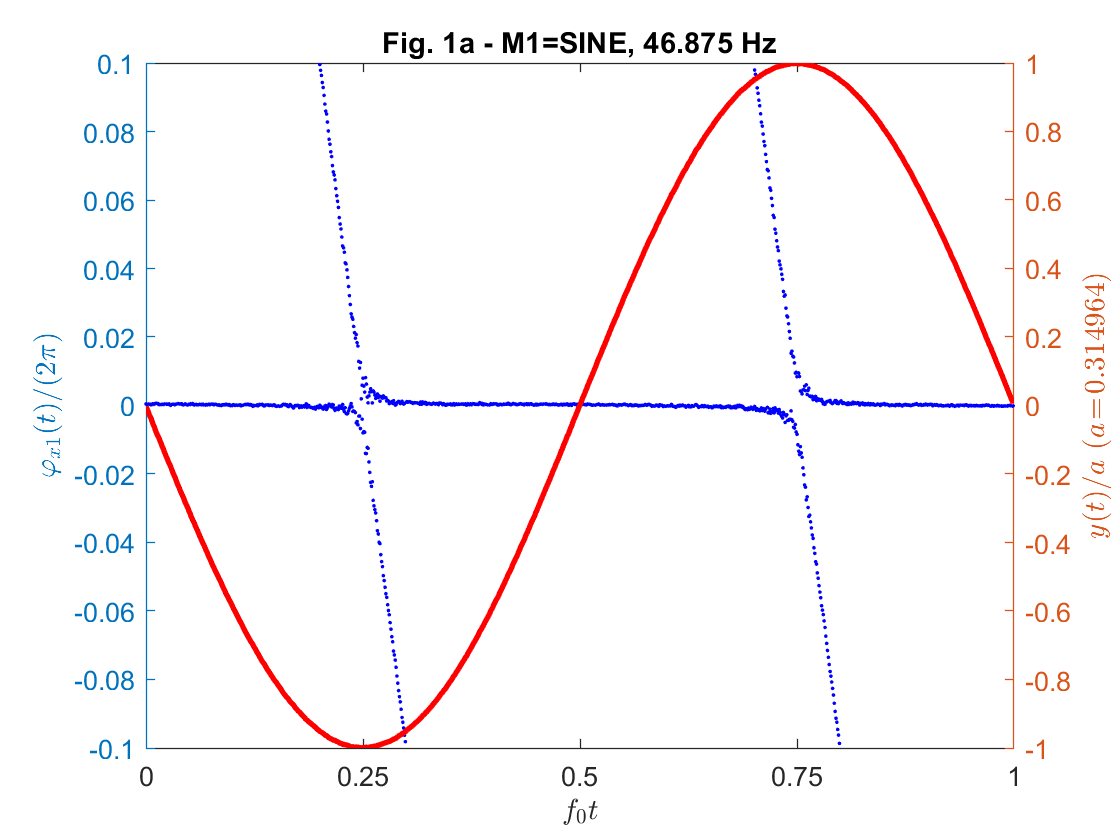

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00

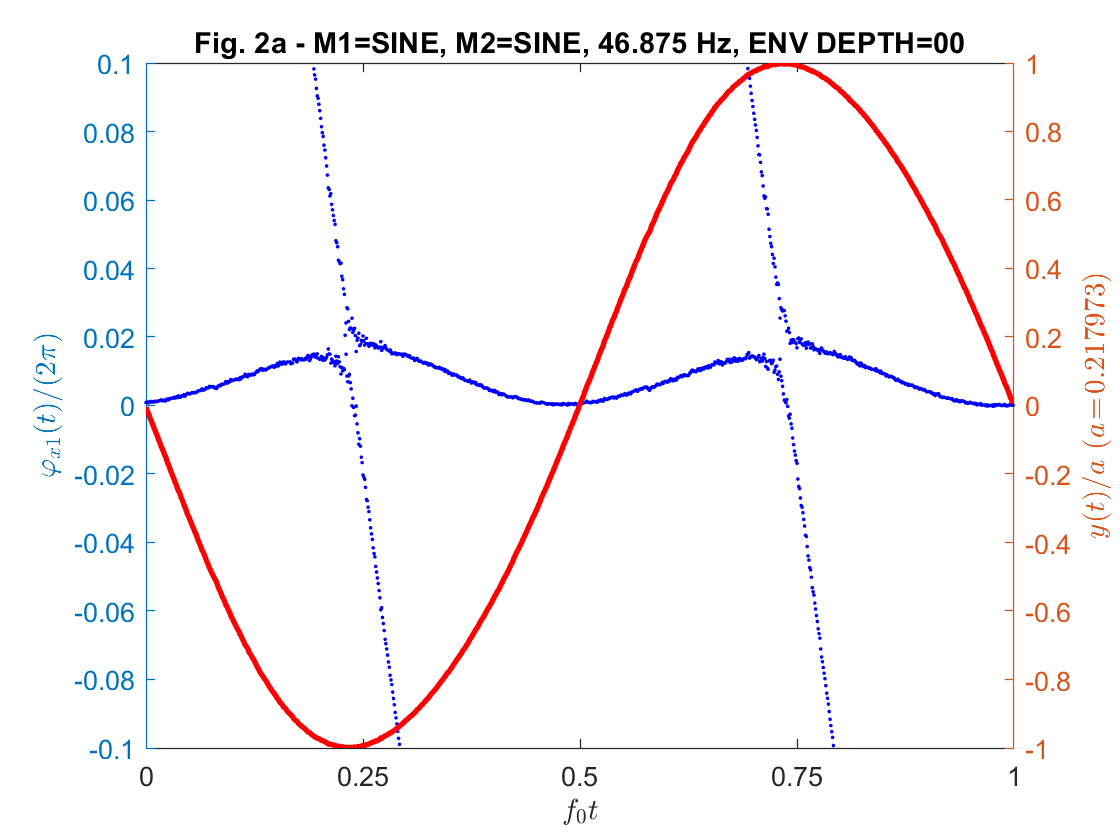

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09

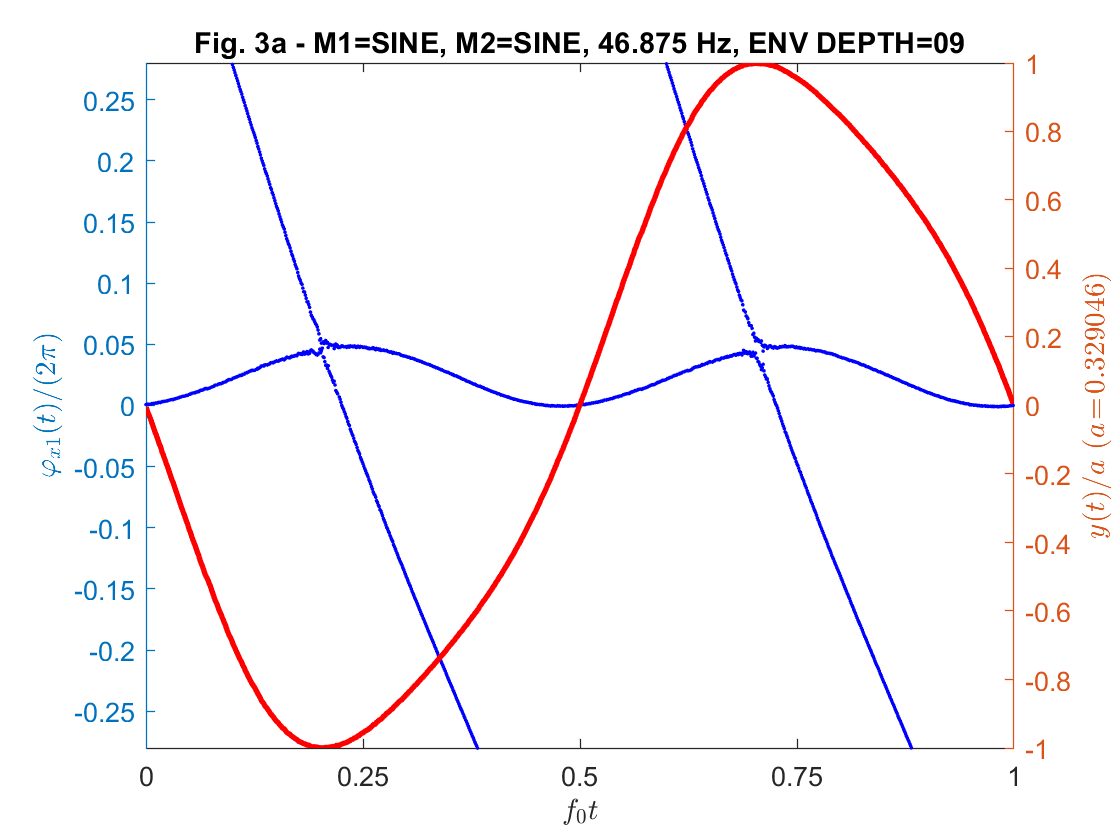

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19

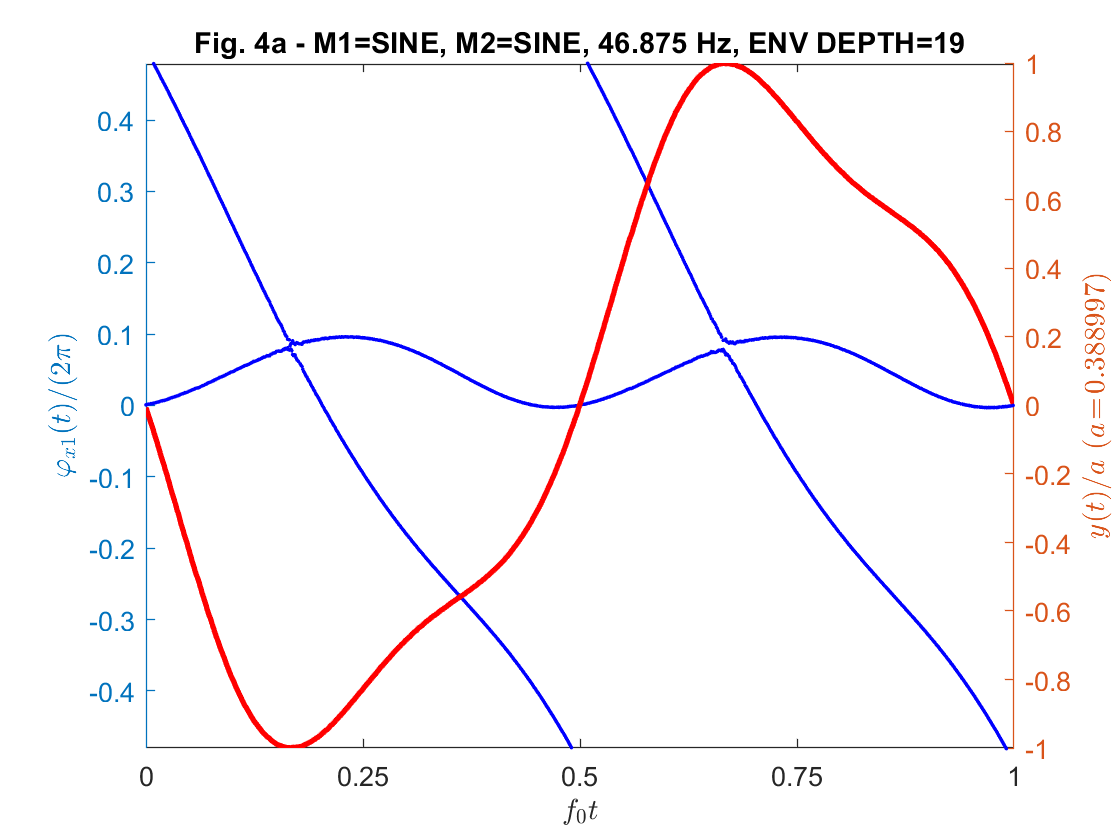

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29

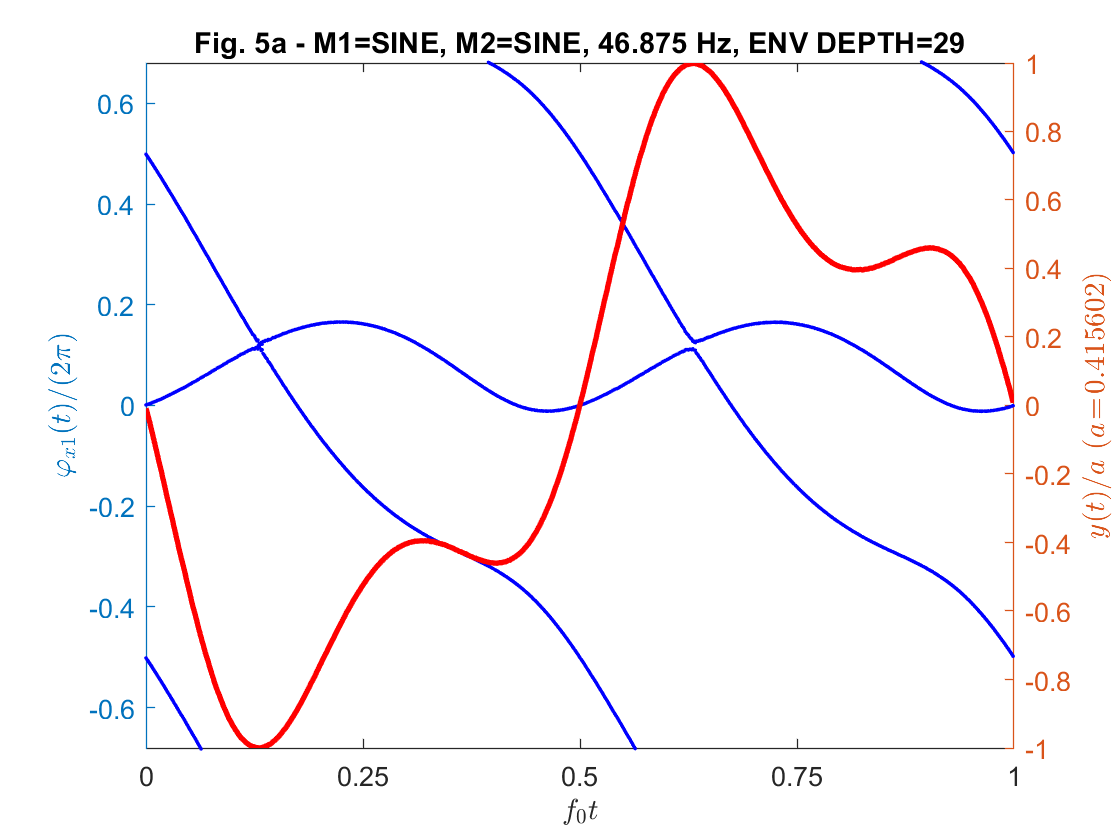

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39

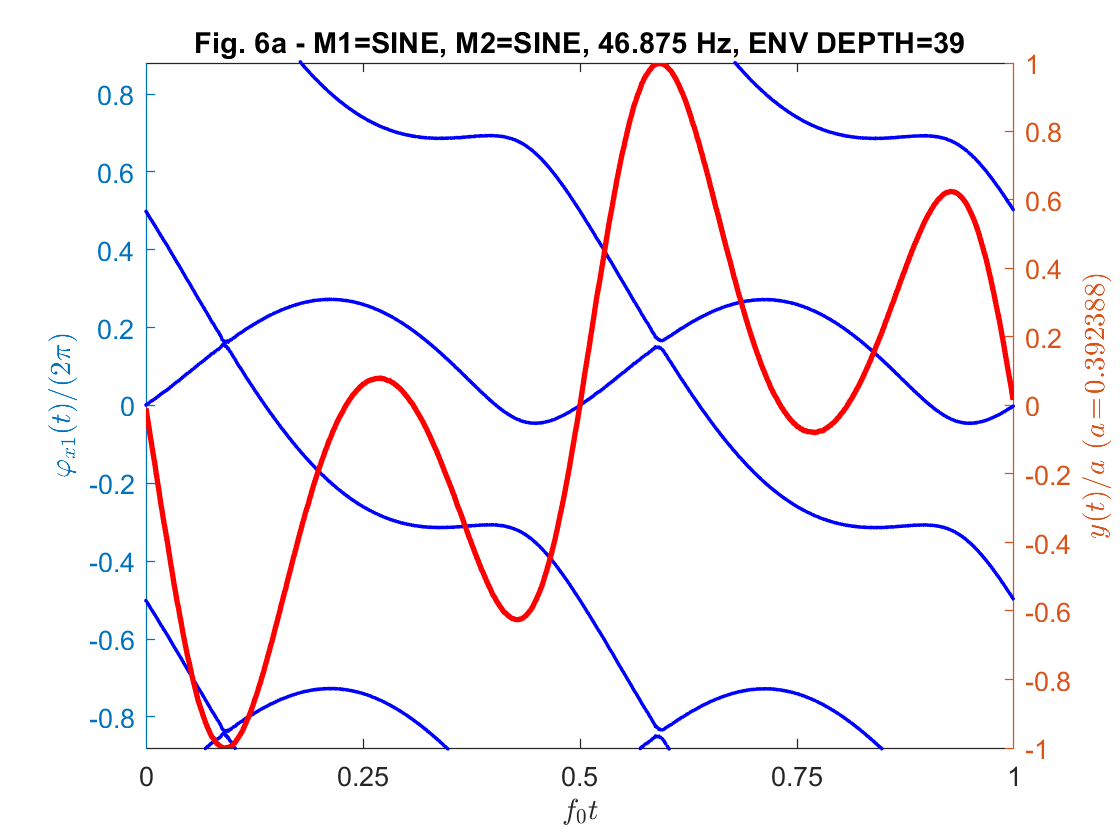

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49

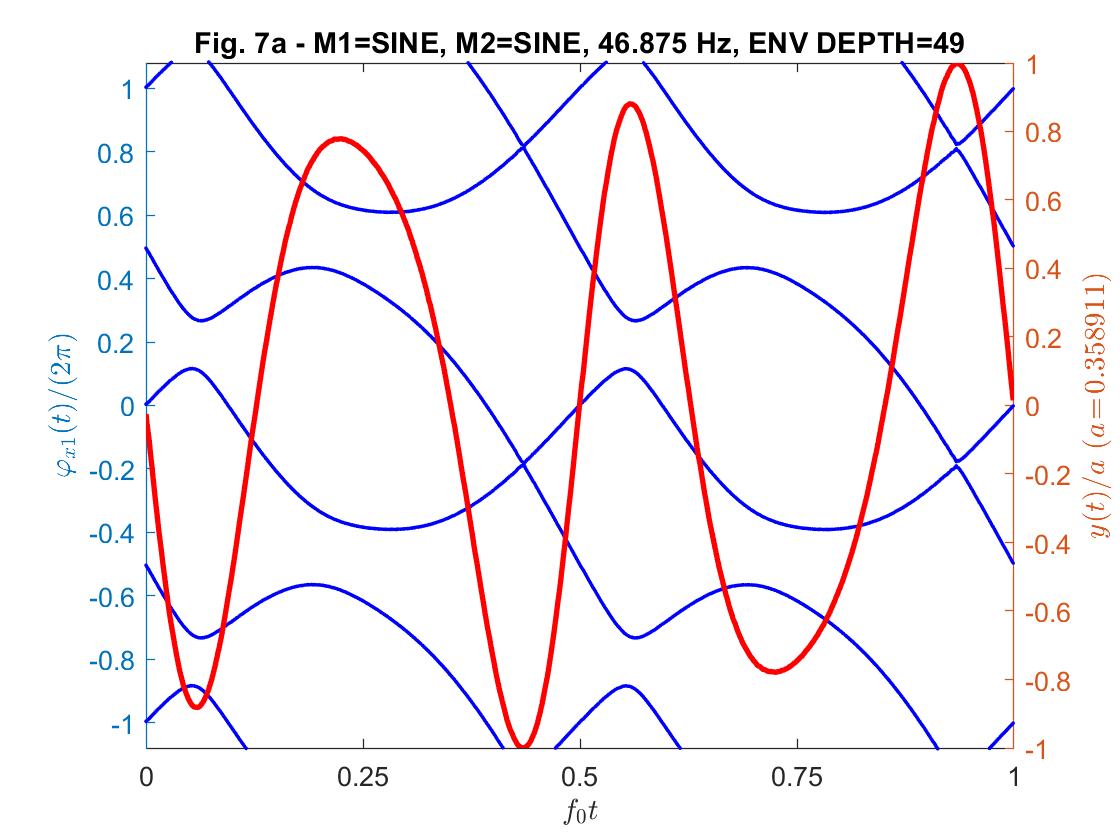

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59

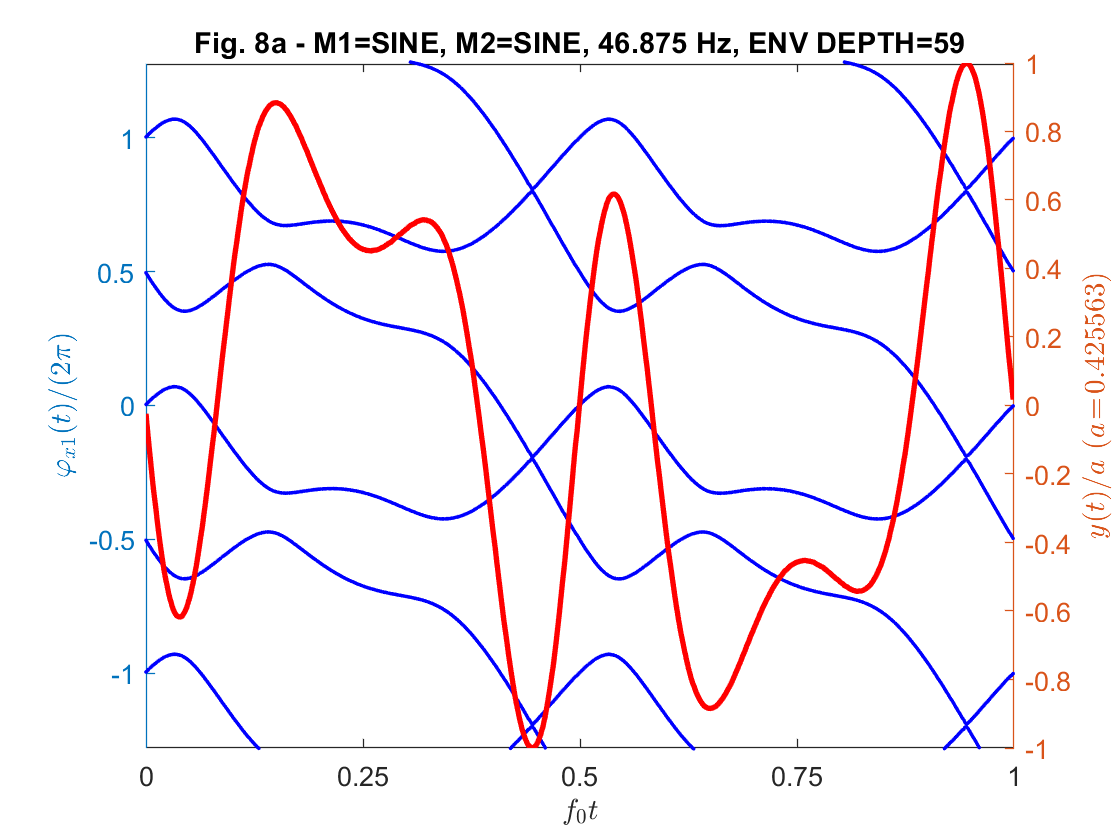

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69

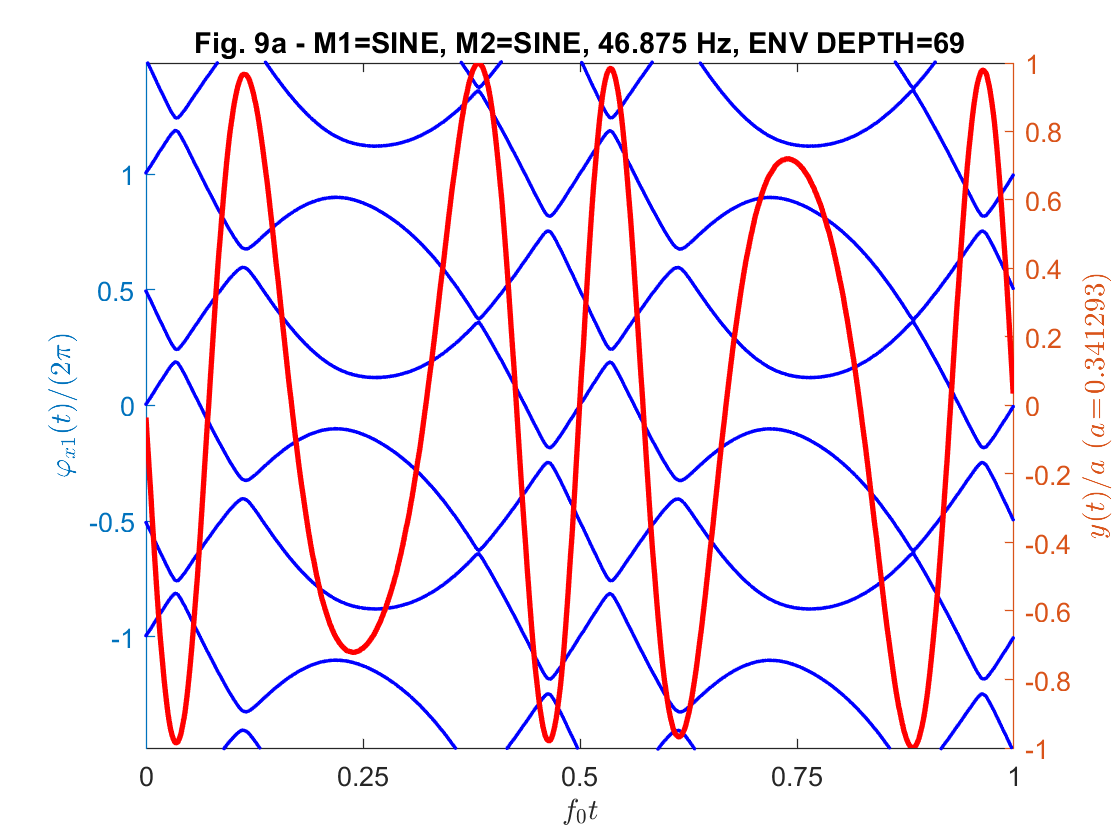

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79

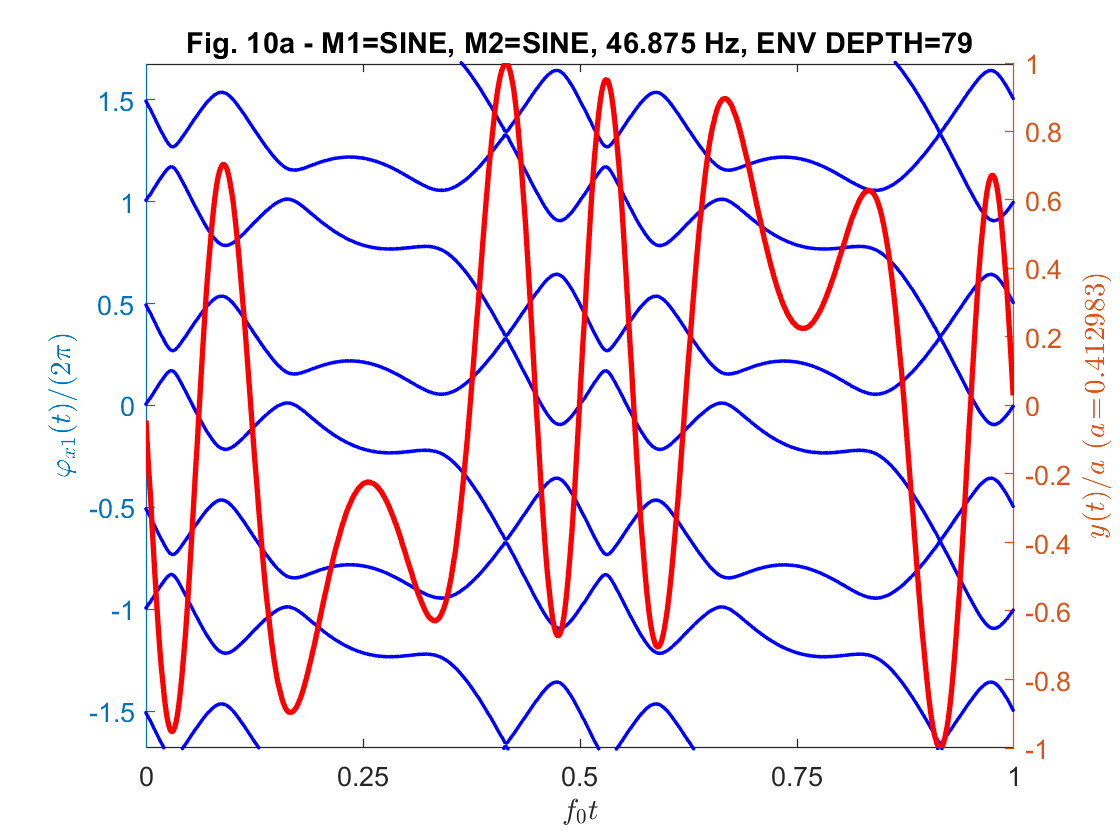

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89

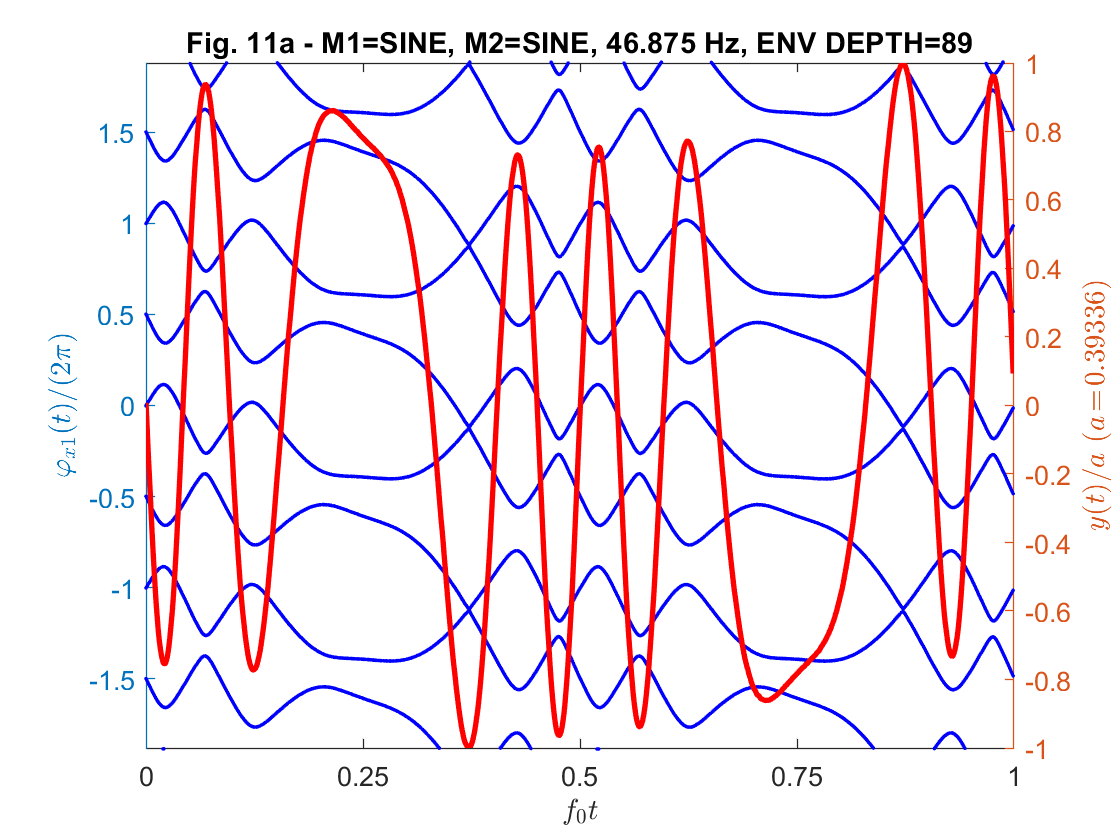

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99

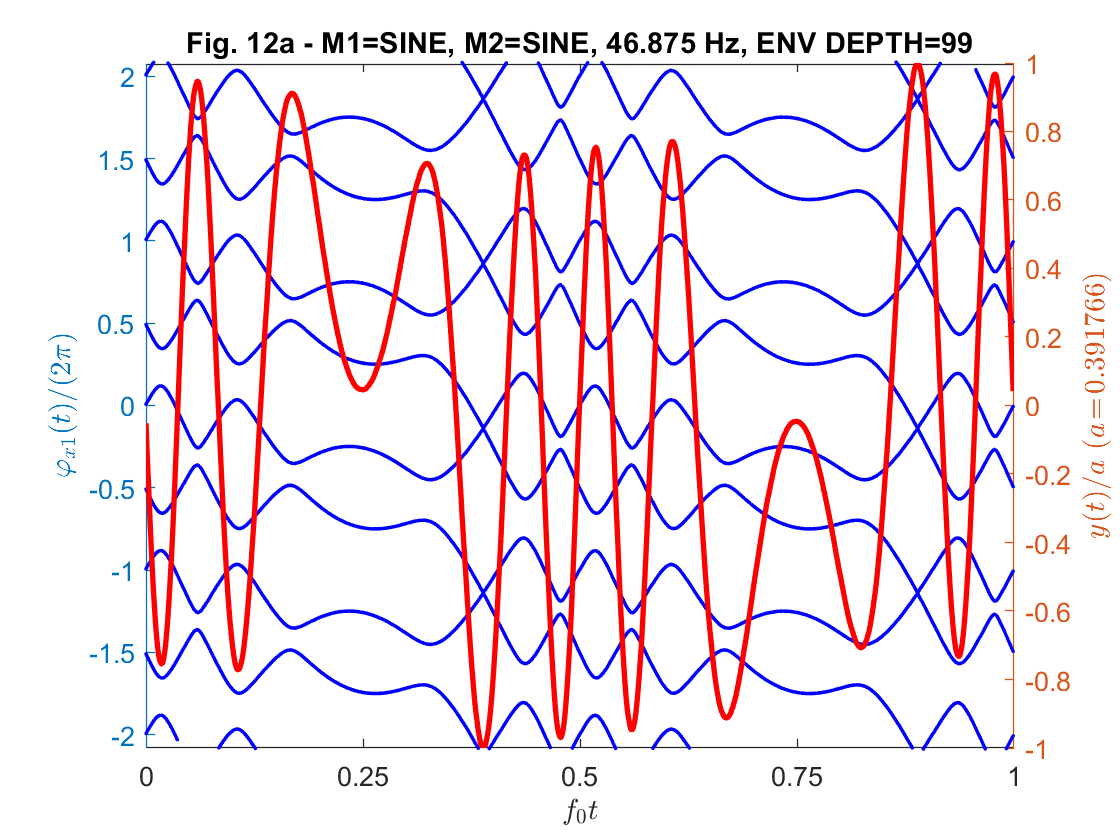

syms p real;
assume(p>0 & p<=2*pi);

for i=1:12
  fprintf('%s',name{i});
  y     = wave{i}/a(i);
  K     = length(y);
  k     = 0:K-1;
  x2    = sin(2*pi.*k/K-pi);
  phix1 = vVZtools.pmInvert(y,x2);
  ft    = sprintf('Fig. %da - %s',i,name{i});
  yl    = [-2*h(i)-0.1 2*h(i)+0.1];
  plotPmAnalysis(y,phix1,zeros(0),ft,yl,a(i));
end

The first plot is a single unmodulated sine just for testing the solver. Plots 2 through 6 (`ENV DEPTH` $\in$ [ `00`, `09`, `19`, `29`, `39` ]) indicate, that $x_2$ might be phase-modulated with the *square* of $x_1$:

    $y(t) = a\cdot \sin\big(2\pi f_0t + 2\pi\,h\,\sin^2(2\pi f_0 t-\pi)\big)$.

I observe that 

- already at `ENV DEPTH=00` there seems to be some modulation,

- the squared sine---if it is a squared sine---exposes little phase and amplitude offsets.

The remaining plots are just a big mess; probably due to phase wrapping... :(

Let's test the square hypothesis. I first read the positions $k_{2\max}$, $k_{2\min}$ and values $\varphi_{2\max}$, $\varphi_{2\min}$ of first maximum and the last minimum the (blue) "squared sines". Then I model the phase function $\varphi_{x1}$ by

    $\varphi_{x1,\text{ MODEL}}(k)=2\pi\,\varphi_{2\max}\,\sin^2\left(2\pi\frac{k}{K}-\pi\right)$      for $0\leq k< K$,

and plot the locations of the maxima, the model phase function and the original phase function.

fprintf(['_____________________________________________________________________\n' ...
 'Test Model']);

_____________________________________________________________________
Test Model

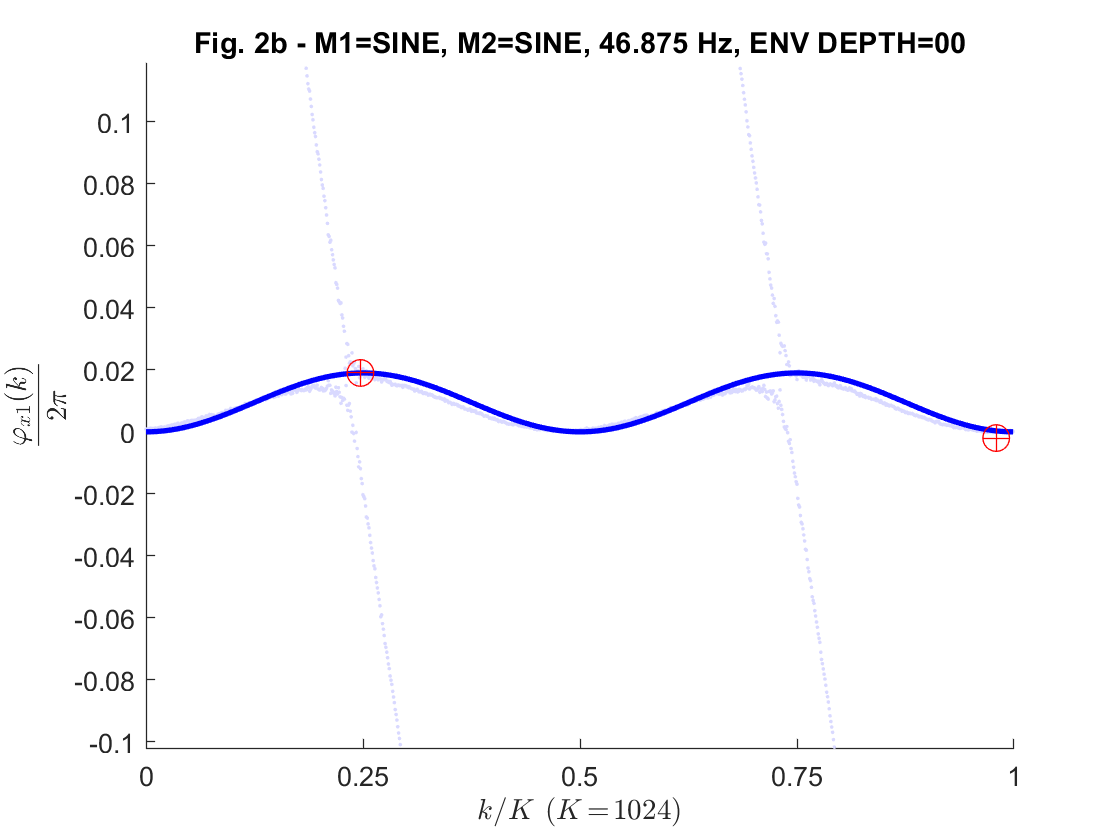

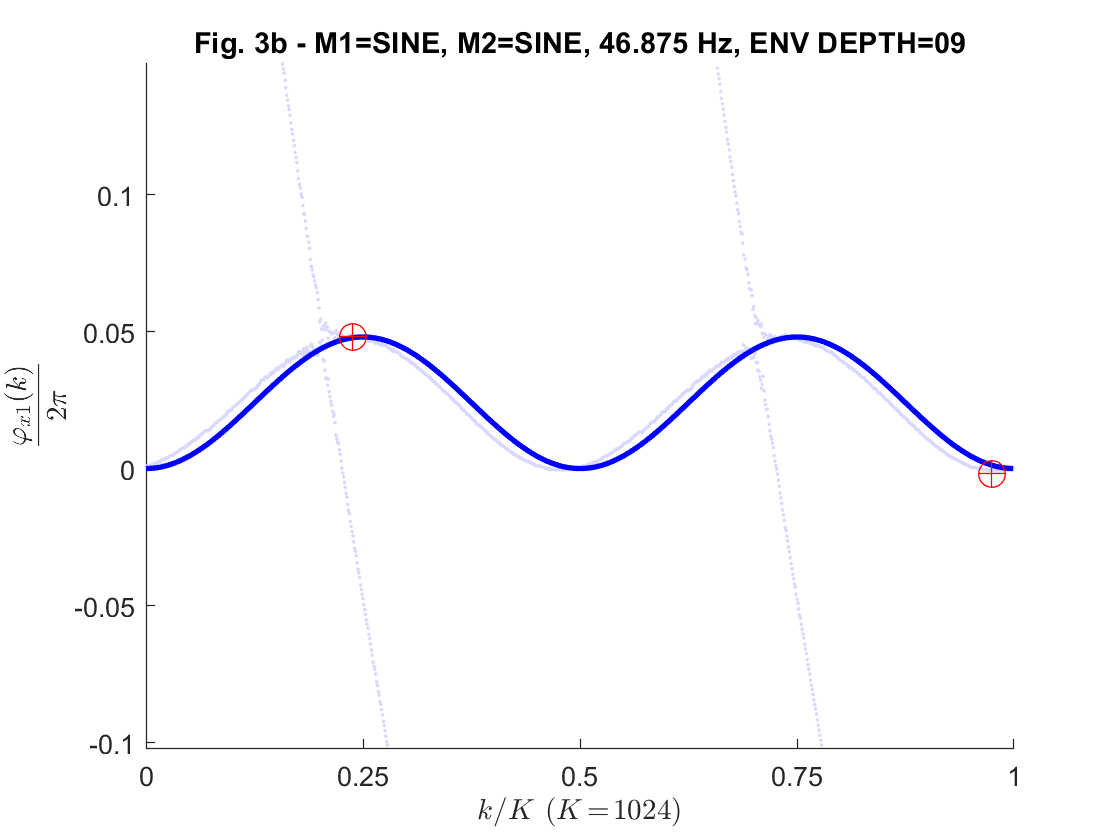

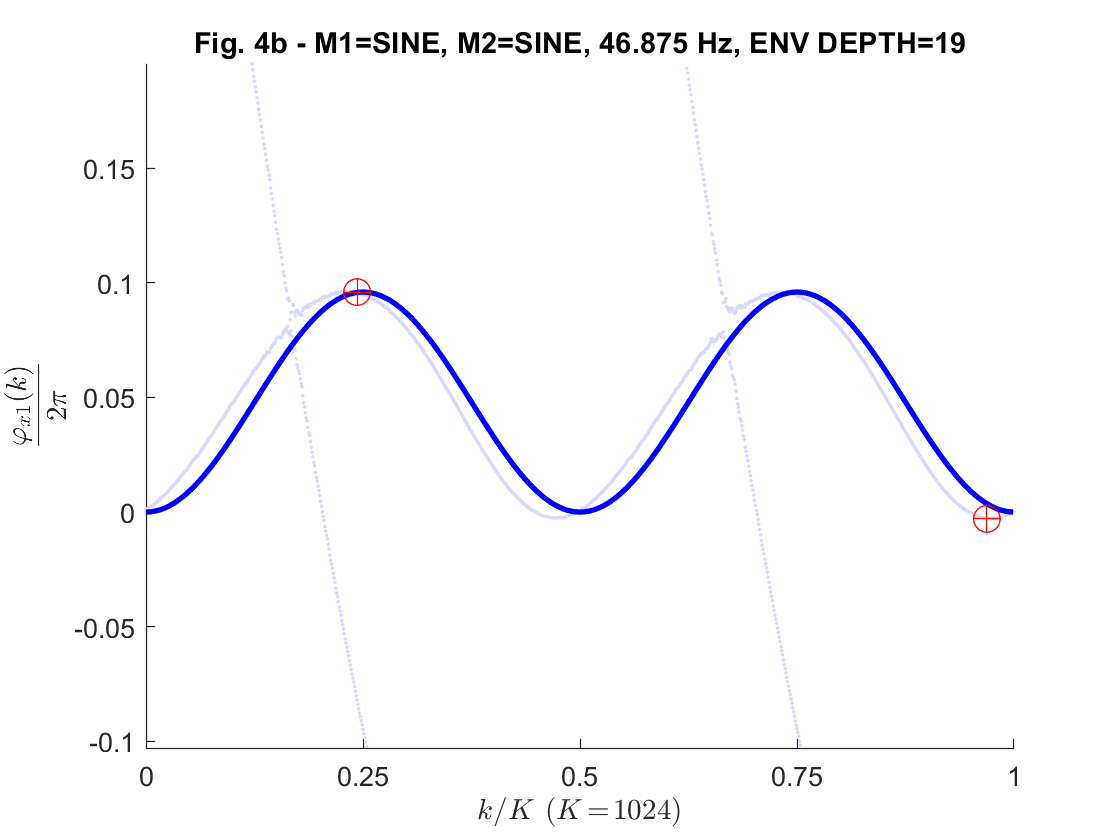

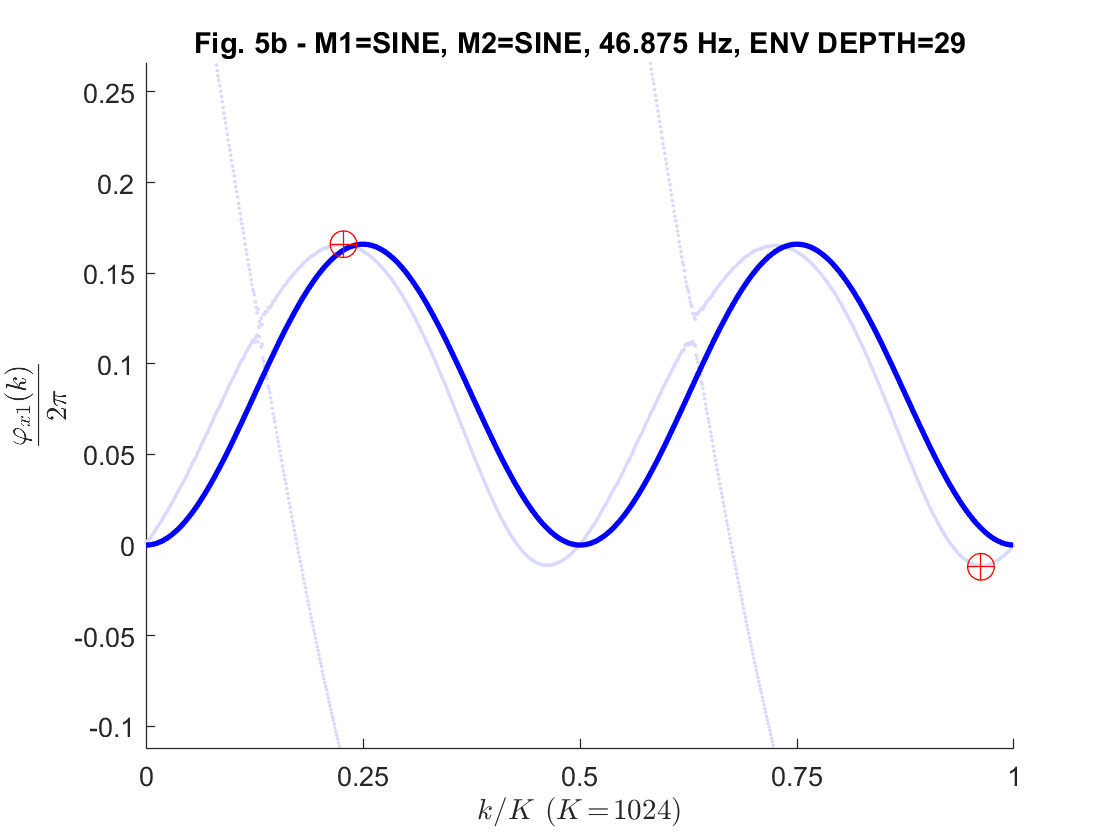

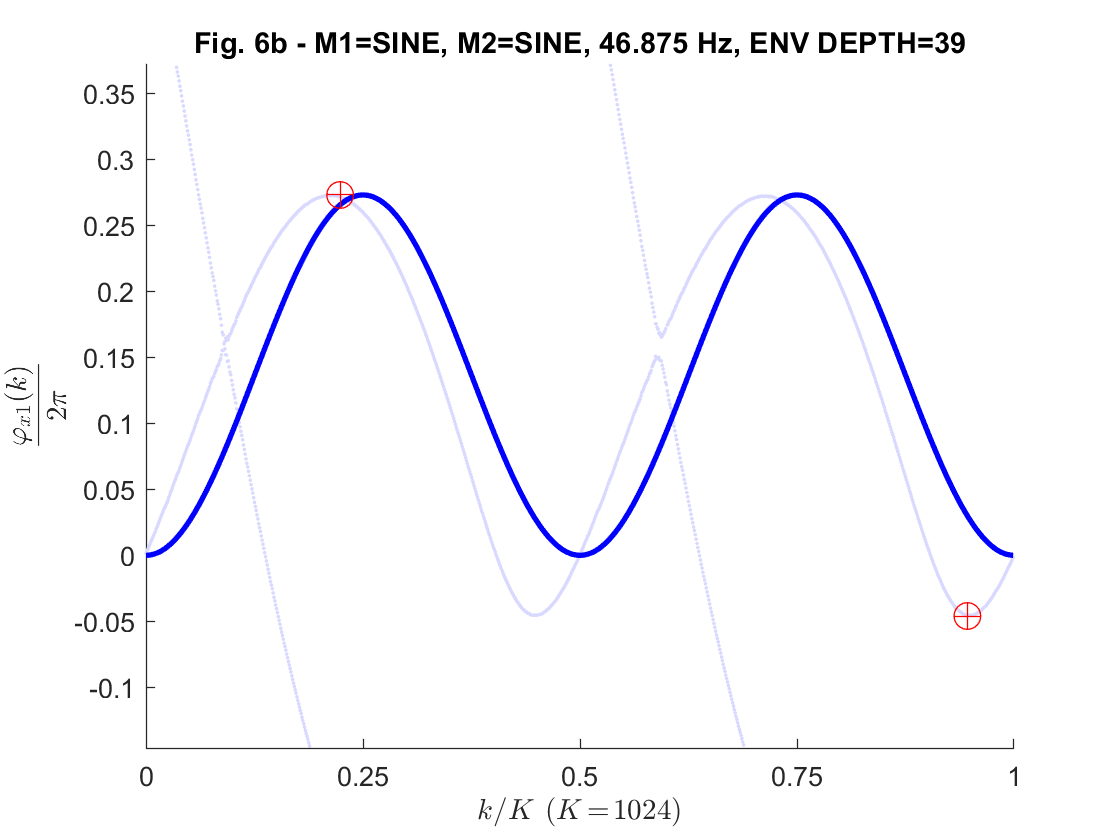

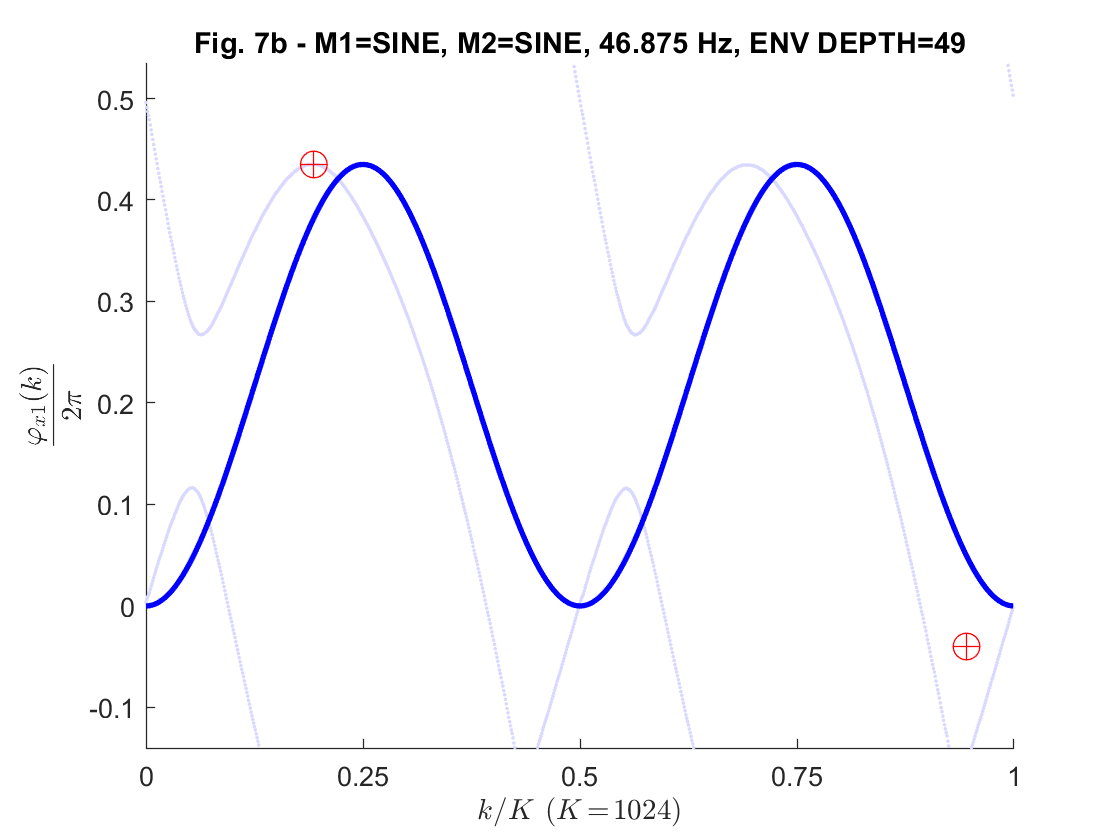

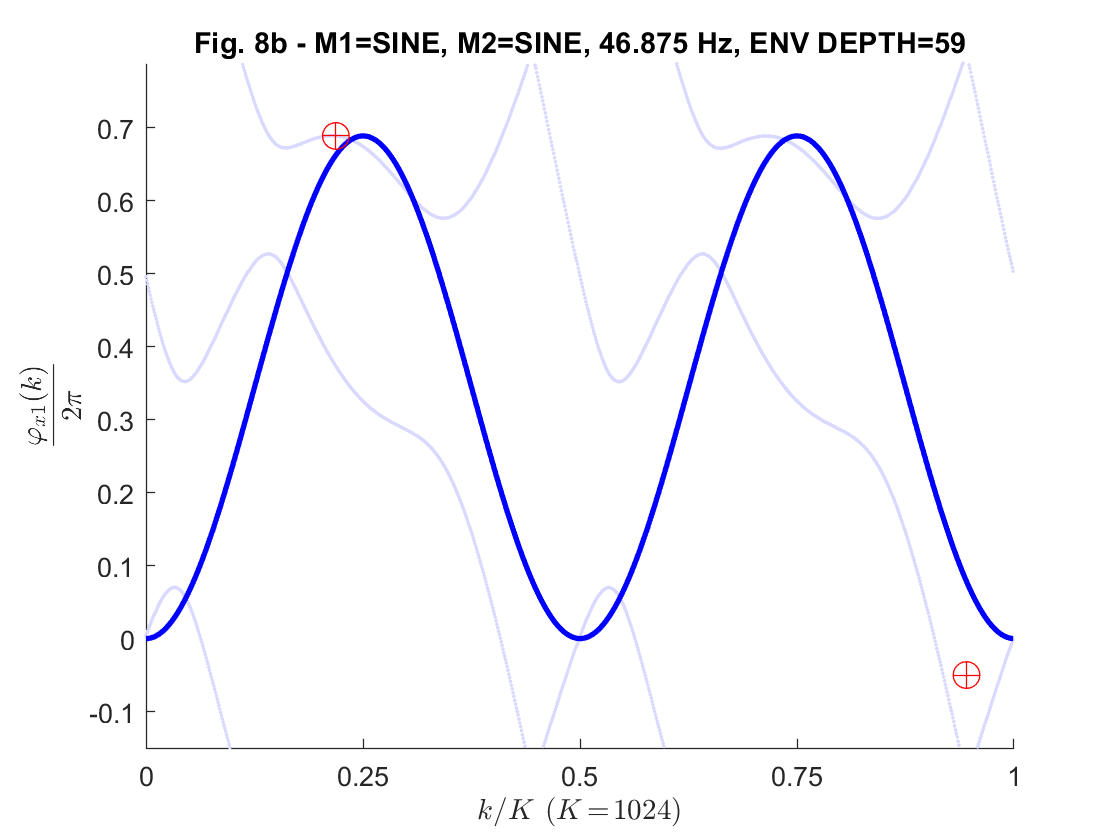

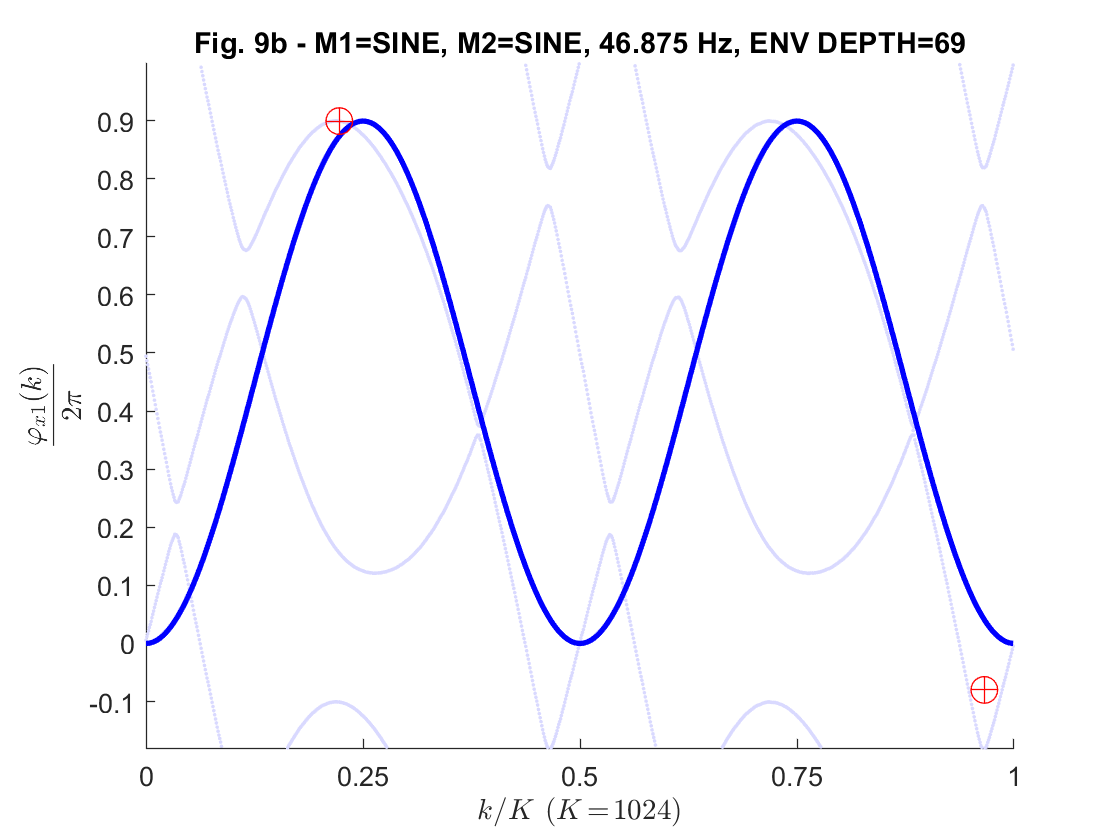


% ENV DEPTH:    00     09     19     29     39     49     59     69     79     89     99
phi2max =  [ 0.019; 0.048; 0.096; 0.166; 0.273; 0.435; 0.689; 0.899; 1.218; 1.5  ; 1.75 ];
k2max   =  [   253;   244;   249;   233;   229;   198;   224;   228;   243;   246;   245];
phi2min =  [-0.002;-0.002;-0.003;-0.012;-0.046;-0.04 ;-0.05 ;-0.08 ;-0.09 ;-0.10 ; -0.10];
k2min   =  [  1003;   998;   992;   985;   969;   968;   968;   989;  1001;   998;  1001];

for i=1:11
  figure;
  y     = wave{i+1}/a(i+1);
  K     = length(y);
  k     = 0:K-1;
  x2    = sin(2*pi.*k/K-pi);
  phix1 = vVZtools.pmInvert(y,x2);
  scatter(phix1(1,:),phix1(2,:),2,'filled','MarkerFaceColor',[0.85 0.85 1]);

  ylim([phi2min(i)-0.1 phi2max(i)+0.1]);
  xlim([0 K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel("$$k/K$$ ($$K\!=\!"+sprintf('%d',K)+"$$)",'Interpreter','latex');
  ylabel('$$\frac{\varphi_{x1}(k)}{2\pi}$$','Interpreter','latex');
  title(sprintf('Fig. %db - %s',i+1,name{i+1}));
  hold on;
  k = 0:K-1;
  plot(k,phi2max(i)*(sin(2*pi.*k/K-pi)).^2,'blue','LineWidth',2);
  scatter([k2max(i) k2min(i)],[phi2max(i) phi2min(i)],100,'+','red');
  scatter([k2max(i) k2min(i)],[phi2max(i) phi2min(i)],100,'o','red');
  hold off;
end

Finally, I simulate the phase modulated signals

    $y_{\text{MODEL}}(k) = \sin\left(2\pi \frac{k}{K}+2\pi\,\varphi_{2\max}\,\sin^2\left(2\pi\frac{k}{K}-\pi\right)-\pi\right)$   for $0\leq k<K$

and plot them together with the respective recorded waveforms $y_{\text{REC}}(k)$:

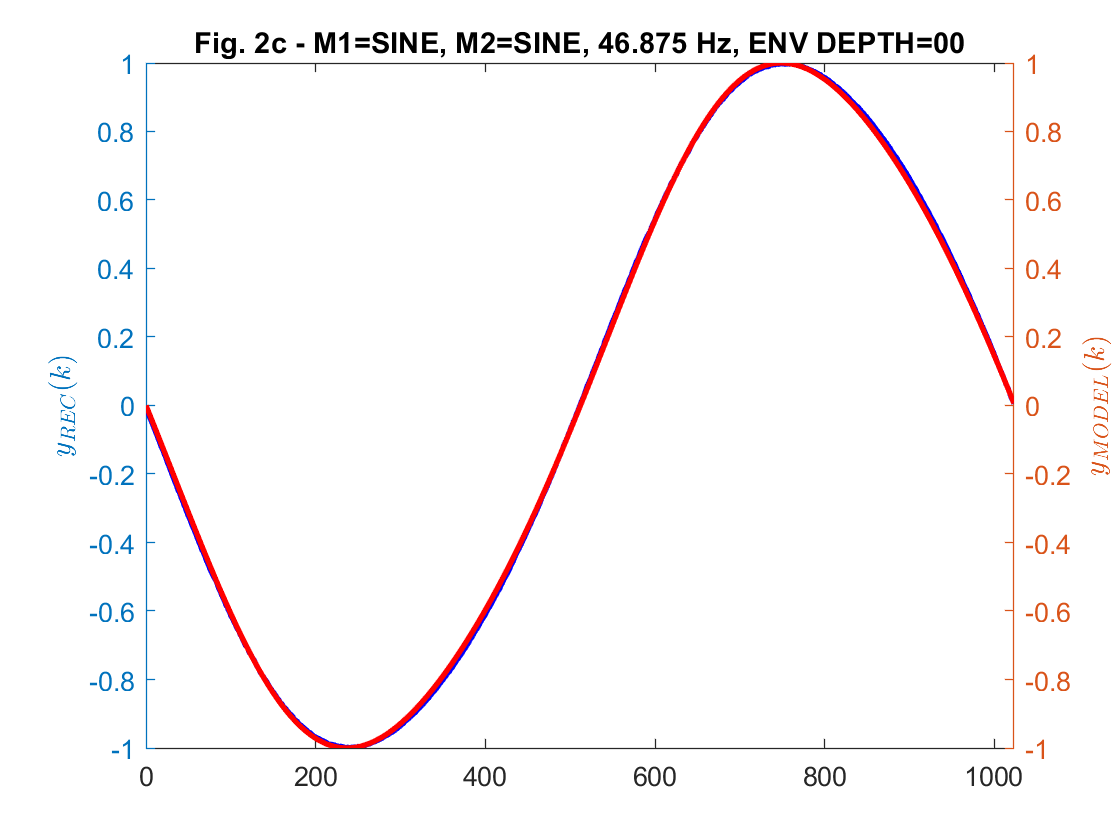

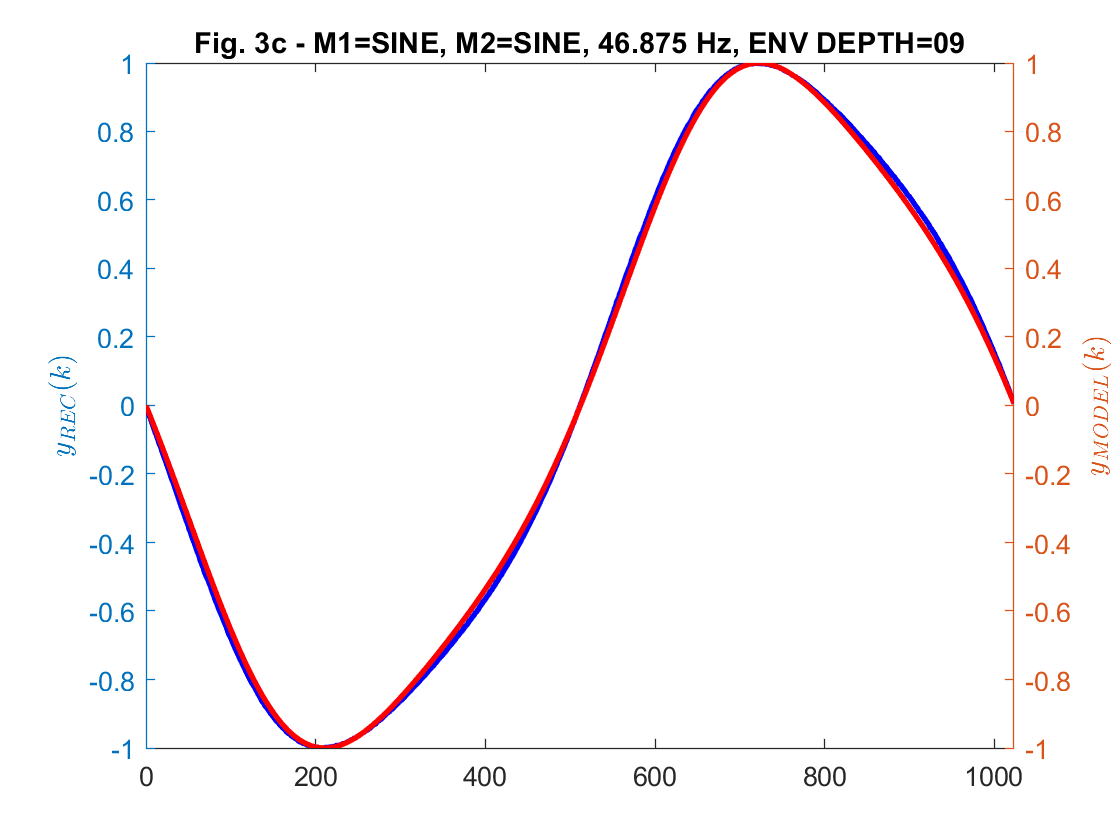

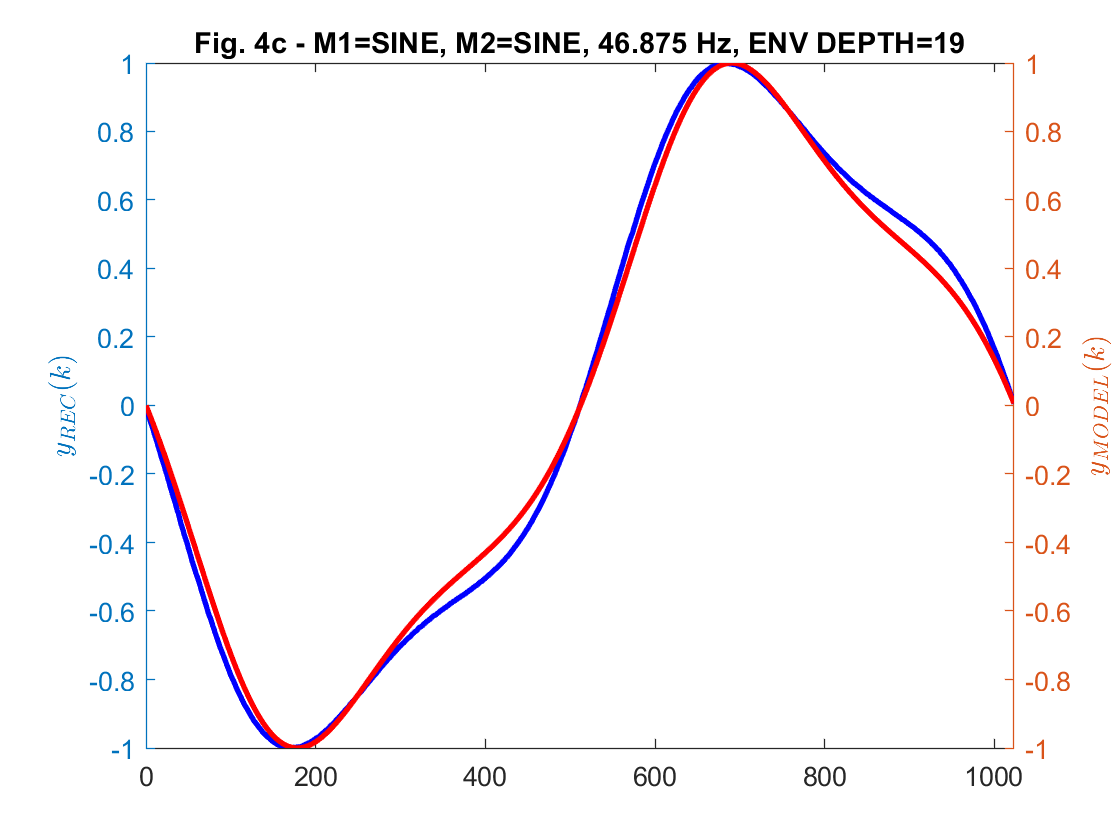

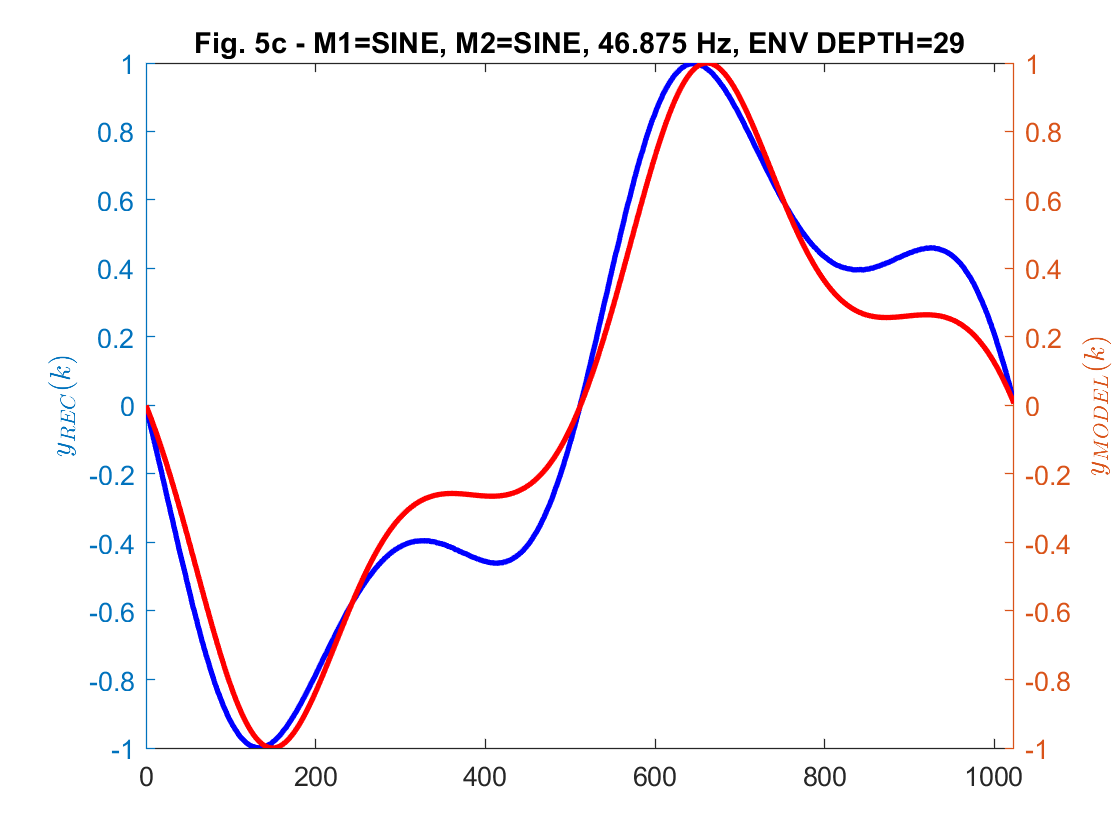

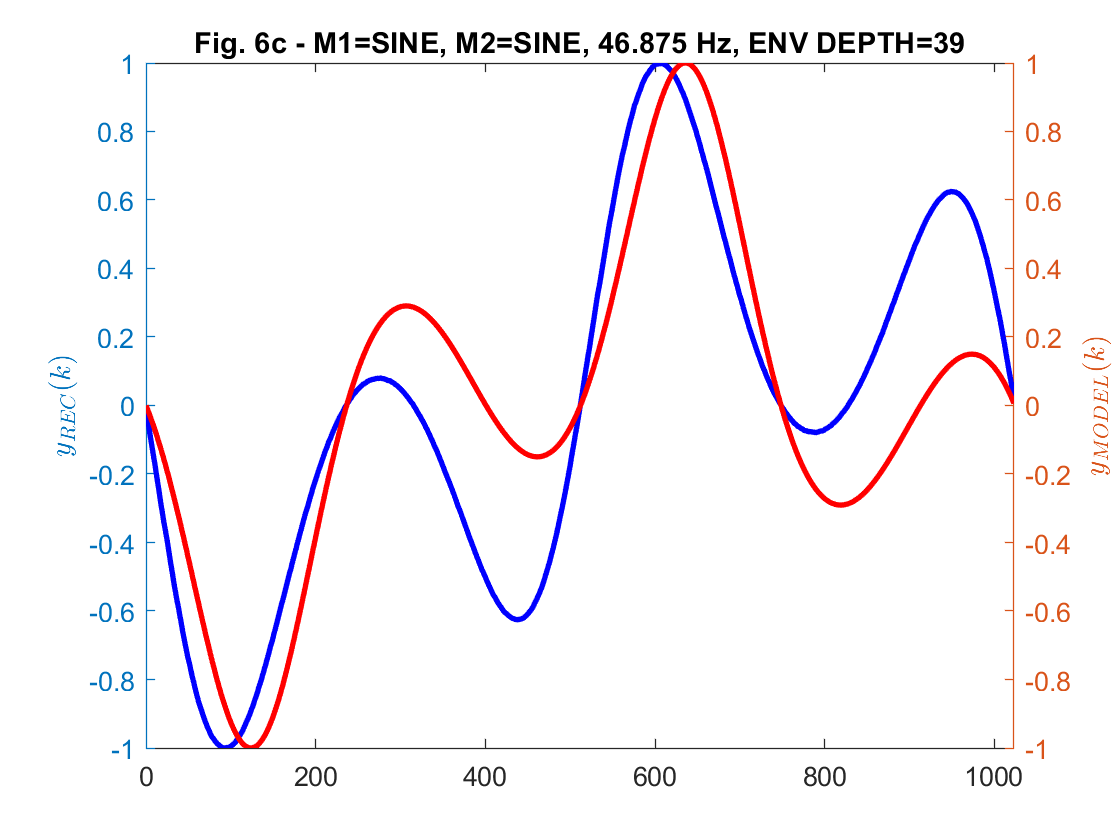

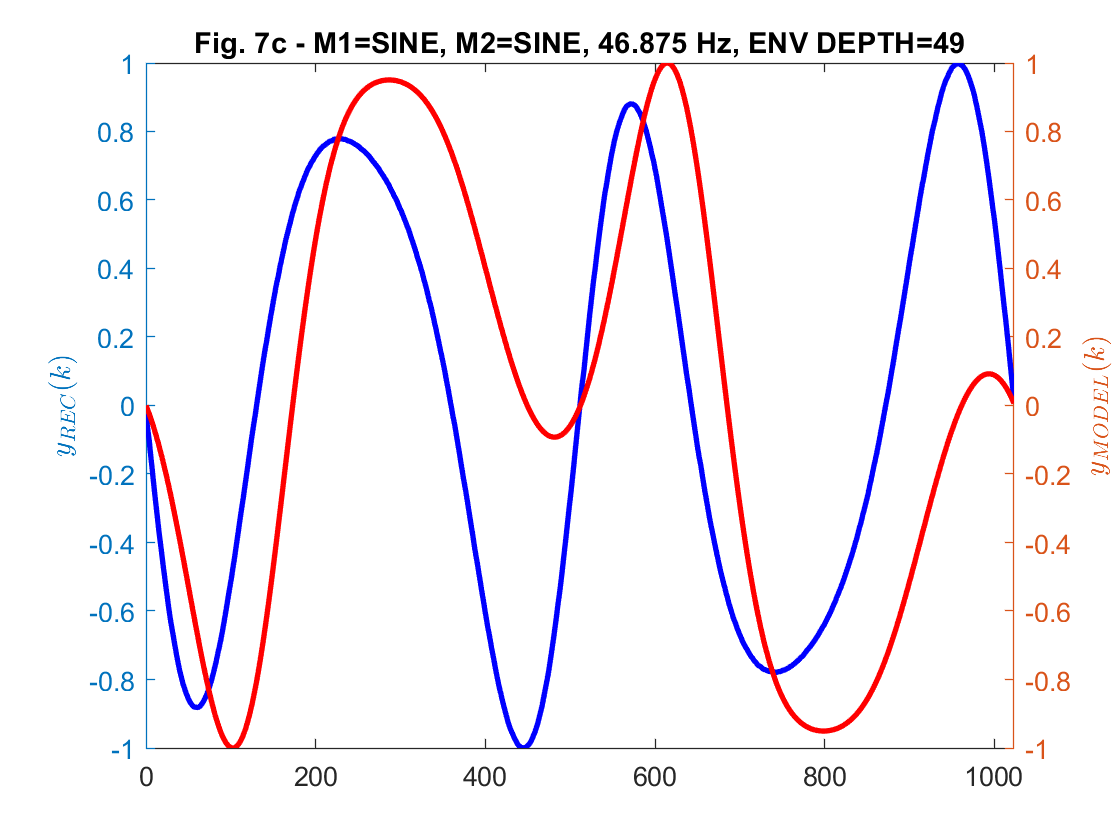

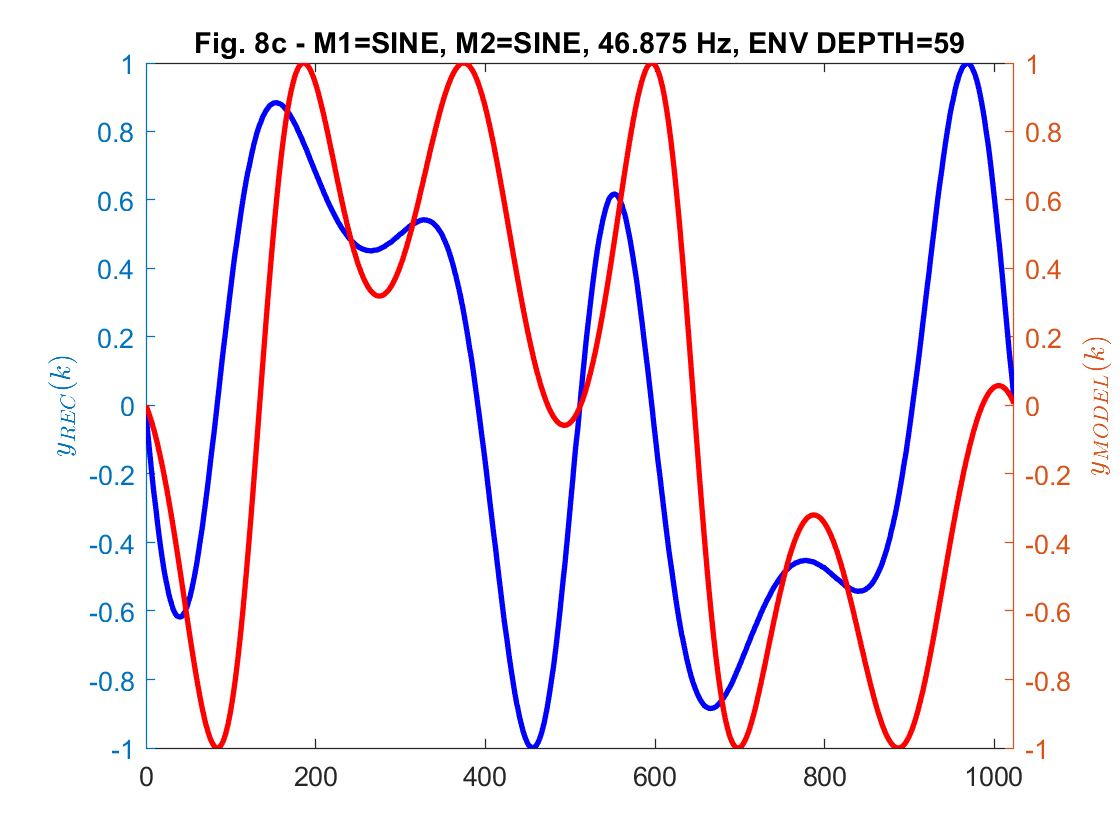

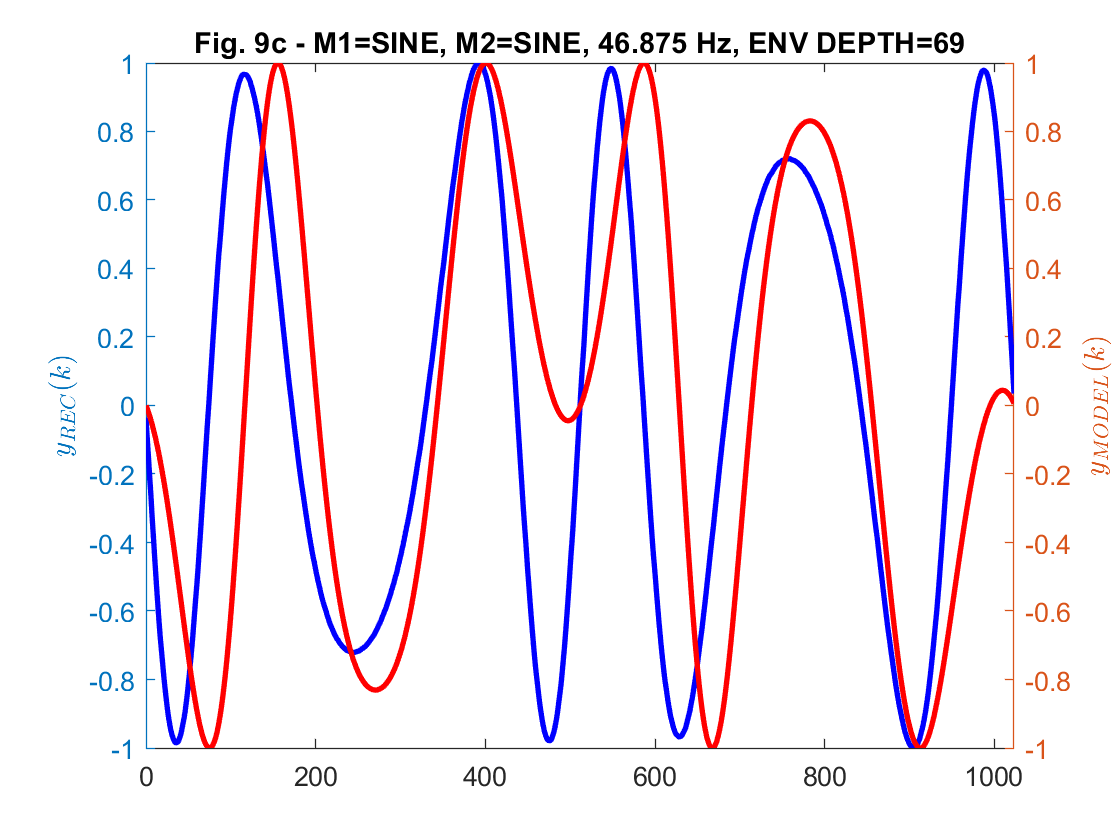

for i=1:11
  K = length(wave{i+1});
  k = 0:K-1;
  Y = sin(2*pi.*k/K + 2*pi*phi2max(i).*power(sin(2*pi.*k/K-pi),2) - pi);
  figure;
  yyaxis left;
  plot(k,wave{i+1}./a(i+1),'LineWidth',2,'Color','blue');
  hold on;
  ylabel('$$y_{REC}(k)$$','Interpreter','latex');
  yyaxis right;
  plot(k,Y,'LineWidth',2,'Color','red');
  ylabel("$$y_{MODEL}(k)$$",'Interpreter','latex');
  title(sprintf('Fig. %dc - %s',i+1,name{i+1}));
  xlim([0,K-1]);
end

Well, I've seen nicer fits. But results are not too bad after all...

**[TODO:** Plot $\varphi_{2\max}$ against `ENV DEPTH`!**]**

### 2.3   `SAWn` v. `SINE` Phase Modulation

**[TODO:** ...**]**

## 3   Conclusion

**[TODO:** ...**]**

Tuned into:

- Sandra: Paintings in Yellow

- Depeche Mode: Playing the Angel

## **Appendix A   Local Functions**

### **A.1   Plot Phase Modulation Analysis**

function plotPmAnalysis(y,x1,x2,ft,yl,a)
  K = length(y);
  k = 0:K-1;
  figure;
  yyaxis right;
  if ~isempty(x2)
    plot(k,x2,'-','LineWidth',2,'Color',[1 0.8 0.8]); hold on;
  end
  plot(k,y ,'-','LineWidth',2,'Color','red'); hold on;
  title(ft);
  xlim([0 K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel('$$f_0t$$','Interpreter','latex');
  ylabel("$$y(t)/a$$ ($$a\!=\!"+sprintf('%g',a)+"$$)",'Interpreter','latex');
  yyaxis left;
  ylabel('$$\varphi_{x1}(t)/(2\pi)$$','Interpreter','latex');
  ylim(yl);
  scatter(x1(1,:),x1(2,:),2,'filled','MarkerFaceColor','blue');
  hold off;
  drawnow;
end